# Explore the dynamics of a 4-dof Robotic manipulator

In this example we're going to derive and then implement the equations of motion for a 4-dof robotic manipulator. Specifically we're going to:

- Derive the equations of motion using's Lagrange's method

The system that we're going to explore is shown below.  At each joint we have:

- $\tau_m$   :     Actuation torques (eg: by electric motors)

- $b.\dot{\theta}$  :    Viscous damping torques

    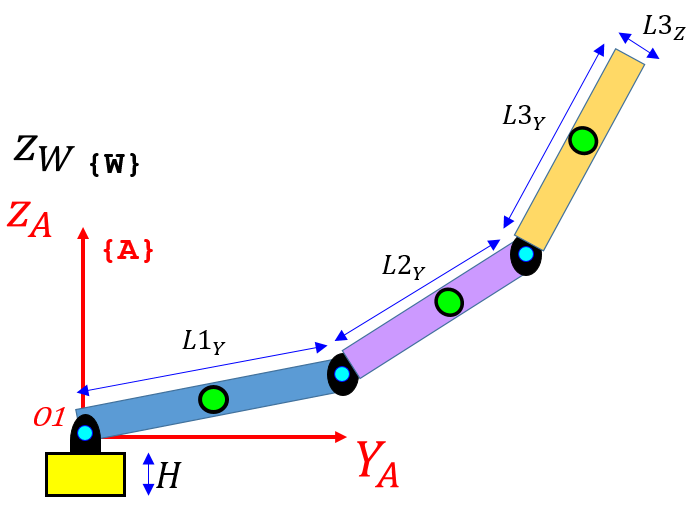   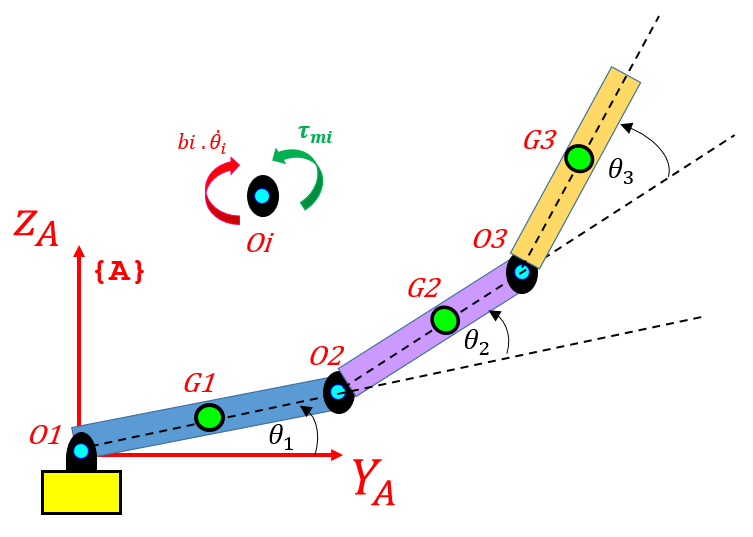   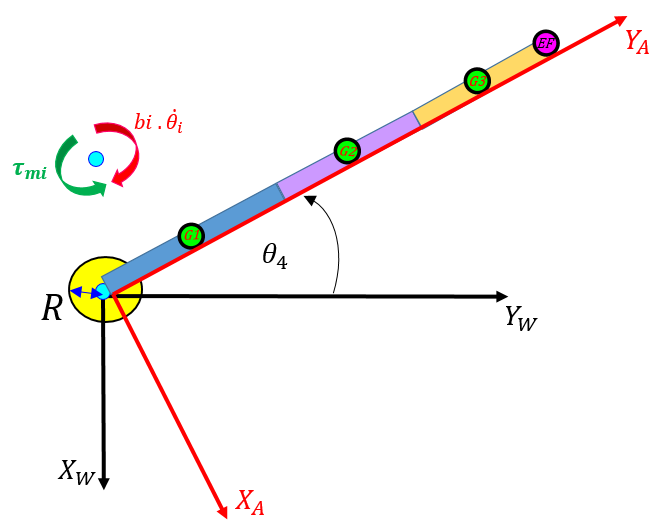         

`Bradley Horton : 13-Sep-2016, bradley.horton@mathworks.com.au`           

# **STAGE 1:** symbolic derivation of system equations

## Euler-Lagrange equations of motion:

The Euler-Lagrange formula will be used to derive the equations of motion for our robotic manipulator, and it has the form:

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system. The Generalised forces can also be defined in terns of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

**Note** : 

- For our system, we will choose  *q = {*$\theta_1 \thinspace, \theta_2 \thinspace, \theta_3 \thinspace, \theta_4$*}* 

- This is a 4 degree of freedom system, and as such there are four 2nd order ODEs that can be derived.

## Defining Model parameters and geometry:

           

Here are some model parameters:

syms    m2_s      m1_s       m3_s       m4_s  % masses
syms    b1_s      b2_s       b3_s       b4_s  % damping
syms taum1_s   taum2_s    taum3_s    taum4_s  % motor torques
syms     g_s                                  % gravity 

syms L1X_s L2X_s L3X_s                        % lengths for LINK #1
syms L1Z_s L2Z_s L3Z_s                        % lengths for LINK #2
syms L1Y_s L2Y_s L3Y_s                        % lengths for LINK #3
syms H4_s  R4_s                               % lengths for TURNTABLE

Here are the angles that describe the pose for our machine.  These 4 angles are also the generalised co-ordinates that we'll use with Lagrange's equation:

syms t theta1(t)  TH1_s  
syms   theta2(t)  TH2_s  
syms   theta3(t)  TH3_s  
syms   theta4(t)  TH4_s  

## Defining component INERTIAs:

The manipulator is made up of 3 rectangular prisms - which form the 3 links of the robotic "arm".  The robot  also has a 4th link which is the cylindrical base or "turntable".  The inertias for these fundamental shapes can be computed about a local body frame positioned at their center of mass (CoM):

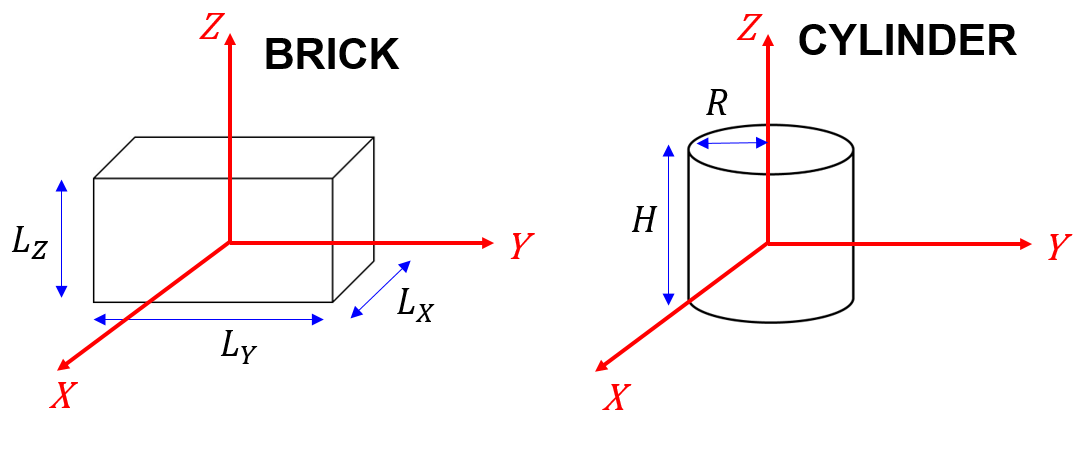   

So let's define the INERTIA matrices for these components about their body fixed **center of mass** frames.  First let's define some formulas for the inertias of these fundamental shapes:

I_brick = @(Lx,Ly,Lz,m)...
    ( [m*(Ly^2 + Lz^2)/12,  0,                   0; ...
                        0,  m*(Lx^2 + Lz^2)/12,  0; ...
                        0,  0,                   m*(Lx^2 + Ly^2)/12;] ); 

I_cyl = @(H,R,m)...
    ( [m*(H^2 + 3*R^2)/12,  0,                   0; ...
                        0,  m*(H^2 + 3*R^2)/12,  0; ...
                        0,  0,                   m*(R^2)/2;] ); 

So the INERTIA matrices for our 4 bodies are:

I1_s = I_brick(L1X_s, L1Y_s, L1Z_s, m1_s);
I2_s = I_brick(L2X_s, L2Y_s, L2Z_s, m2_s);
I3_s = I_brick(L3X_s, L3Y_s, L3Z_s, m3_s);
I4_s = I_cyl(H4_s,  R4_s, m4_s);

As a concrete example, here's what the inertia matrix for Link 1, looks like:

I1_s

## Define Center of mass positions and TRANSLATIONAL velocities for ARM links:

In the diagrams below, we've defined the inertial(fixed) World co-ordinate frame to be at the pivot point between links 1 and 4 - this {W}-frame is fixed in space ... it does NOT move.  We've also defined a frame called the {A-frame} - the {A}-frame shares the same origin as the {W}-frame, however the {A}-frame may rotate about the common $^WZ$and $^AZ$axes.  We've attached **body fixed** co-ordinate frames to the center of mass(CoM) of each of the 4 links.  So note the following frames:

- *{W}-frame is our INERTIAL frame*

- *{A}-frame* rotates with robot about the common $^WZ$and $^AZ$axes

- *{B1}-frame* is attached to CoM of Link 1

- *{B2}-frame* is attached to CoM of Link 2

- *{B3}-frame* is attached to CoM of Link 3

- *{B4}-frame* is attached to CoM of Link 4

     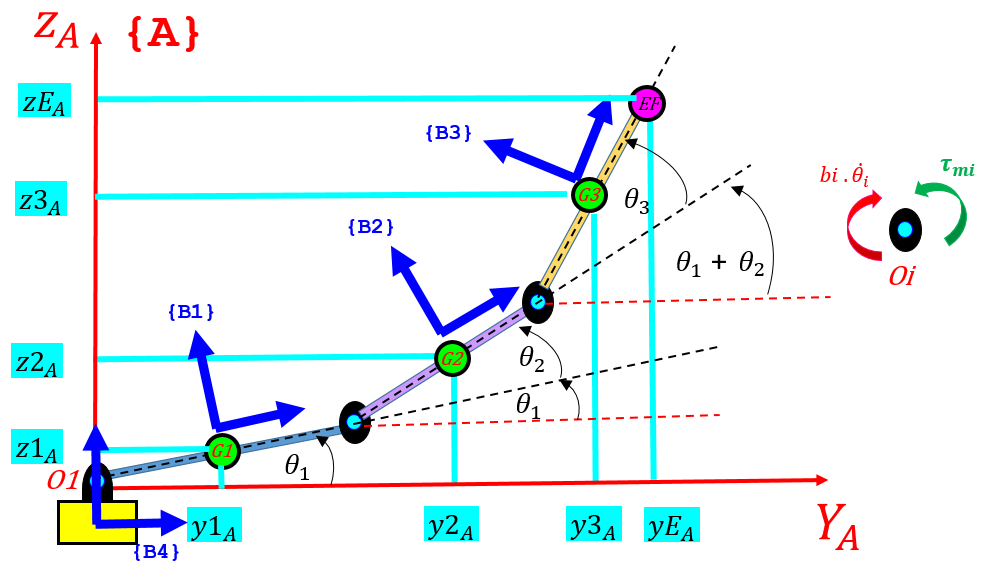     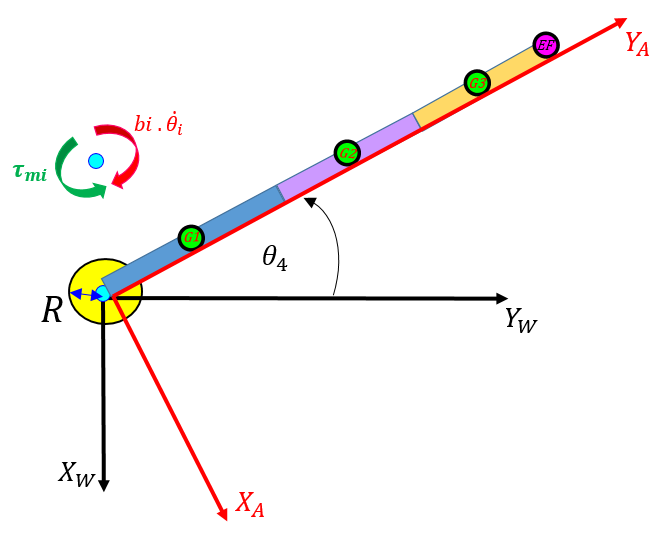    

First, let's define the x,y,z position of the **centre of mass** (CoM) for each link - and we'll define these positions in terms of the {A}-Frame.  And after we've done this, we'll convert the CoM positions to our inertial {W}-frame, and then we can differentiate to get translational velocities: 

**Consider LINK_1:** *- where is the CoM relative to the {A}-Frame*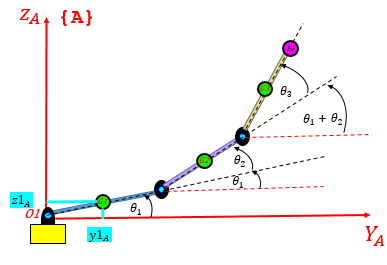

AF_pos_G1      = sym([0;0;0]);
AF_pos_G1(2,1) = (L1Y_s/2)*cos(theta1(t));
AF_pos_G1(3,1) = (L1Y_s/2)*sin(theta1(t));

**Consider LINK_2:** *- where is the CoM relative to the {A}-Frame *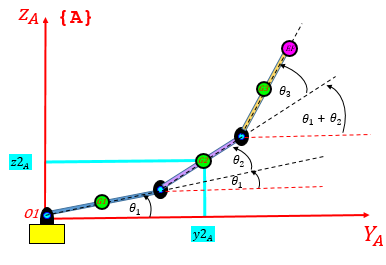

alpha          = theta1(t) + theta2(t);
AF_pos_G2      = sym([0;0;0]);
AF_pos_G2(2,1) = L1Y_s*cos(theta1(t)) + (L2Y_s/2)*cos(alpha);
AF_pos_G2(3,1) = L1Y_s*sin(theta1(t)) + (L2Y_s/2)*sin(alpha);

**Consider LINK_3:** *- where is the CoM relative to the {A}-Frame *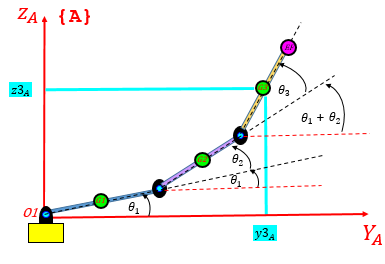

beta           = theta1(t) + theta2(t) + theta3(t);
AF_pos_G3      = sym([0;0;0]);
AF_pos_G3(2,1) = L1Y_s*cos(theta1(t)) + L2Y_s*cos(alpha) + (L3Y_s/2)*cos(beta);
AF_pos_G3(3,1) = L1Y_s*sin(theta1(t)) + L2Y_s*sin(alpha) + (L3Y_s/2)*sin(beta);

We can now convert these {A}-Frame co-ordinates into their corresponding {W}-frame co-ordinates using the following transformation $^Wr = {^WR}_A \thinspace . \thinspace ^Ar$:

   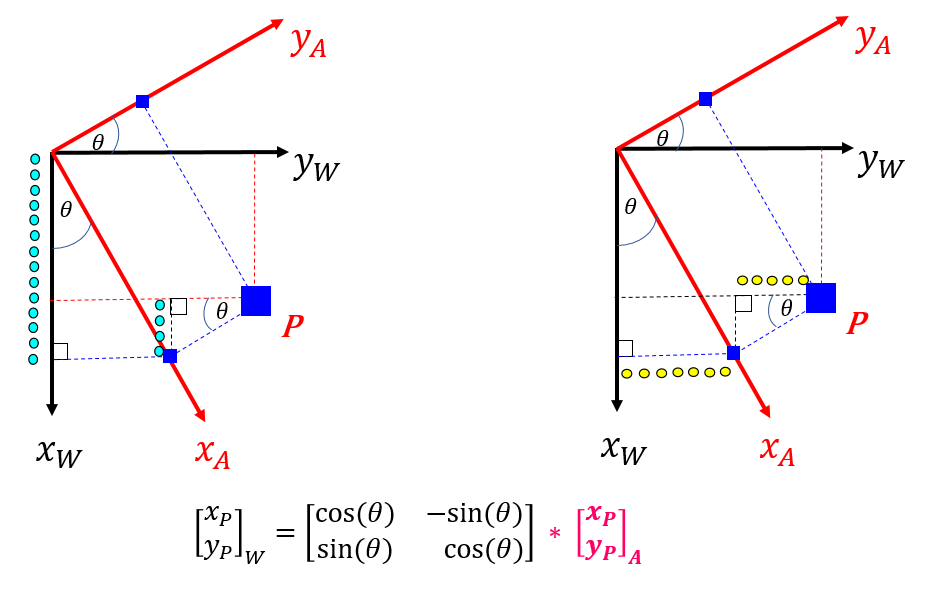

wRa = [ cos(theta4(t)),  -sin(theta4(t)),   0;
        sin(theta4(t)),   cos(theta4(t)),   0;
                     0,                0,   1 ]

So our {W}-Frame position co-ordinates for the link center of masses are:

WF_pos_G1 = wRa * AF_pos_G1;  
WF_pos_G2 = wRa * AF_pos_G2;  
WF_pos_G3 = wRa * AF_pos_G3;                  

As a concrete example, here's the {x,y,z} co-ordinate of the centre of mass for LINK-3, expressed in the {W}-frame:

WF_pos_G3

Now calculate our ***translational velocities*** for each  arm link and express in terms of the {W}-Frame:

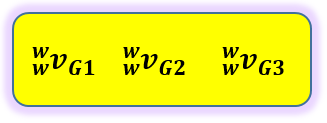

WF_tran_vel_G1 = diff( WF_pos_G1, t);  
WF_tran_vel_G2 = diff( WF_pos_G2, t);   
WF_tran_vel_G3 = diff( WF_pos_G3, t);  

As a concrete example, here's what the translational velocity vector $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack$ looks like for the center of mass of Link #1,  expressed in components of the INERTIAL {W}-frame:

WF_tran_vel_G1

## Define ROTATIONAL velocities for all bodies:

    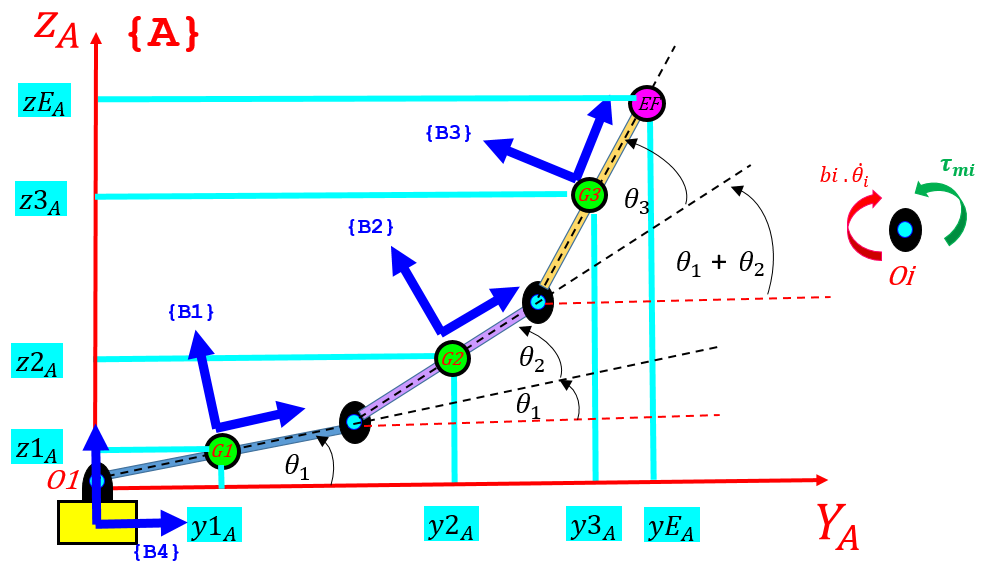        

Next we're going to define the rotational velocities for our 4 bodies. And we're going to express these rotational velocities in components of the local centre of mass BODY fixed frames attached to each body - this is a natural approach because a body fixed frame means our inertias stay constant relative to that frame.  The angular velocities that we'll define are:

- $^{B1}\omega_1 :$ is the angular velocity of LINK 1, expressed in components of the {B1}-Frame

- $^{B2}\omega_2 :$ is the angular velocity of LINK 2, expressed in components of the {B2}-Frame

- $^{B3}\omega_3 :$ is the angular velocity of LINK 3, expressed in components of the {B3}-Frame

- $^{B4}\omega_4 :$ is the angular velocity of TURNTABLE, expressed in components of the {B4}-Frame

Note also, we can use the following transformation matrix, to convert an {A}-Frame vector into it's {B}-Frame components - we'll use this to convert our TURNTABLE angular velocity into components of the LINK body fixed frames. WHY? - the total angular velocity of an individual arm link is a vector sum which will include the contribution of the turntable angular velocity.  So for for LINKS {1,2,3}, we'll specify the total angular velocity as:

- 
$${}^{Bi}_{\text{ }}{\omega }^{\text{ }}_i=\text{ }{}^{Bi}_{\text{ }}R^{\text{ }}_A\ldotp {}^A_{\text{ }}{\omega }^{\text{ }}_A\text{   }+\text{   }{}^{Bi}_{\text{ }}{\omega }^{\text{ }}_{i\mid A}$$
      

where:   ${}^{\text{Bi}}_{\text{ }}{\omega }^{\text{ }}_{i\text{∣}A}$ is the angular velocity of LINK-i releative to the {A}-frame.

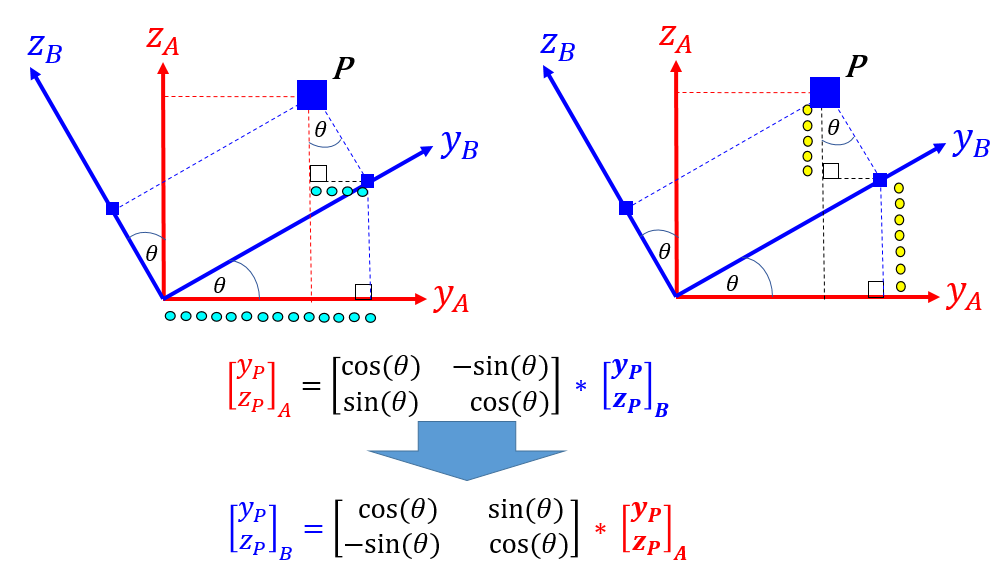

*NOTE:   in the code below, we've created "function handle" variables to parameterise the rotation matrix *$^BR_A$* .*

bRa = @(th) [       1,          0,         0;
                    0,    cos(th),   sin(th);
                    0,   -sin(th),   cos(th); ];

OK, so let's do it.  First let's define the angular velocity of the turntable (ie Link #4) ... which is the same thing as our {A}-frame angular velocity:

BF_rot_vel_B4 = [0;0; diff(theta4(t))];
AF_w          = [0;0; diff(theta4(t)) ];

Next, let's define the angular velocity for LINKS {1,2,3}.  Note that in addition to the local link rotation angles, we also have the turntable rotation angle.  So our link angular velocities are:  ${}^{\text{Bi}}_{\text{ }}{\omega }^{\text{ }}_i=\text{ }{}^{\text{Bi}}_{\text{ }}R^{\text{ }}_A\ldotp {}^A_{\text{ }}{\omega }^{\text{ }}_A\text{   }+\text{   }{}^{\text{Bi}}_{\text{ }}{\omega }^{\text{ }}_{i\text{∣}A}$

       

th1           = theta1(t)                        ;
th12          = theta1(t) + theta2(t)            ;
th123         = theta1(t) + theta2(t) + theta3(t);

BF_rot_vel_B1 = bRa(th1  )*AF_w  +  [diff(th1)   ; 0; 0];
BF_rot_vel_B2 = bRa(th12 )*AF_w  +  [diff(th12)  ; 0; 0];
BF_rot_vel_B3 = bRa(th123)*AF_w  +  [diff(th123) ; 0; 0];

As a concrete example, here's what the angular velocity vector $^{B2}\omega_2 =$$\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$, looks like, for Link 2 and expressed in components of the body fixed {B2}-frame:

BF_rot_vel_B2

## Define the system KINETIC energy:

Next we'll use our previously derived expressions for body velocities and use them to define the "system" Kinetic Energy for our machine.  Because we've attached our BODY frames to the **centre of masses** of every link, the kinetic energy for the $i^{th}$ link can be stated as:


$${\text{KE}}_i =\text{ }\frac{1}{2}{v_{{\text{cm}}_i }^T {\ldotp m}_i } {\text{ }\ldotp v}_{{\text{cm}}_i } \text{ }\text{ }\text{ }+\text{    }\text{ }\frac{1}{2}\ldotp \omega_{B_i }^T \ldotp \left\lbrack I_{{cm}_i } \right\rbrack \ldotp \omega_{B_i }$$


The total system kinetic energy is then just the sum of the "*N*" individual link kinetic energies, ie:


$${KE}_{system} =\text{ }\sum_{i=1}^{N} {KE}_i$$


   

Our TRANSLATIONAL kinetic energy is:

KE_trans = 0.5*m1_s * (WF_tran_vel_G1.') *  WF_tran_vel_G1   + ...
           0.5*m2_s * (WF_tran_vel_G2.') *  WF_tran_vel_G2   + ...
           0.5*m3_s * (WF_tran_vel_G3.') *  WF_tran_vel_G3        ;

Our ROTATIONAL kinetic energy is:

KE_rot   = 0.5 * (BF_rot_vel_B1.') * I1_s *  BF_rot_vel_B1  + ...
           0.5 * (BF_rot_vel_B2.') * I2_s *  BF_rot_vel_B2  + ...
           0.5 * (BF_rot_vel_B3.') * I3_s *  BF_rot_vel_B3  + ...
           0.5 * (BF_rot_vel_B4.') * I4_s *  BF_rot_vel_B4;           

So our total system kinetic energy is:

KE = KE_trans + KE_rot;      

## Define the system POTENTIAL energy:

Similarly we can define our "system" Potential Energy:

Our system Potential energy is:

PE = g_s*( m1_s*WF_pos_G1(3)  + m2_s*WF_pos_G2(3)  + m3_s*WF_pos_G3(3)  );

## Define the system Lagrangian:

Next define our system Lagrangian:

L_ORIGINAL = KE - PE;

Note the symbolic variables that are inside the Lagrangian:

symvar(  L_ORIGINAL  )

***IFFF*** you really wanted to see what the terms inside the Lagrangian looked like (are you sure?) ... then we could echo them:

the_list_of_terms_making_up_L = children(L_ORIGINAL);
the_list_of_terms_making_up_L(:)

To derive the equations of motion for our machine, "all" we need to do is a series of derivative calculations according to Lagrange's equation:

 
$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $$
 

Where:

- *L = KE - PE, *is our system lagrangian

- *q = {*$\theta_1 \thinspace, \theta_2 \thinspace, \theta_3 \thinspace, \theta_4$*}*  are the generalised co-ordinates for our 4-dof manipulator

- $Q_k$ are the generalised forces (Torques) for our system

## Apply Lagrange's equation:

So let's now apply Lagrange's equation:

-  $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

First we'll create some variables that define our generalised co-ordinates.  I'm going to use 2 sets of these generalised co-ordinates:

- the **ACTUAL** set of symbols are our "proper" set of symbols

- the **HOLDER** set are for easier expression manipulation (these are purely for convenience)

actual_list_SYM_pos = formula( [ theta1,      theta2,      theta3  ,  theta4]  );
holder_list_SYM_pos = [             TH1_s,       TH2_s        TH3_s,     TH4_s];

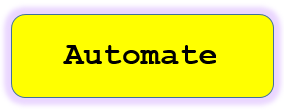     

OK:  let's create a Lagrangian object using the class <`bh_lagr4manips_CLS`>

lag_OBJ = bh_lagr4manips_CLS( KE, PE, actual_list_SYM_pos, holder_list_SYM_pos);

And let's compute the system's equations of motion:

lag_OBJ = lag_OBJ.calc_eom()

So what do the equations of motion actually look like ? - they are long equations involving many terms

lag_OBJ.show_eom()

You can also(if you want to) look at these equations in a text file called `<bh_tmp_EOM_file_WILL_BE_DELETED.txt>`:

lag_OBJ.show_eom_in_txt_file()

If you want to look at an individual equation of motion (eg: the LHS of the $\theta_4$ equation), then you could do this:

lag_OBJ.get_eom(4, 'actual', 'LHS')

In a moment we'll show how to "collect" the terms in these EOMs and present them in a format that looks like this:

- 
$$M(q).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q$$


# **Define the Generalised forces:**

Next we need to calculate our Generalised forces.  Recall the formula for the generalised forces acting on the system:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

Define some angular velocities:

th1dot     = formula( diff(theta1, t)  );
th2dot     = formula( diff(theta2, t)  );
th3dot     = formula( diff(theta3, t)  );
th4dot     = formula( diff(theta4, t)  );

For each link, I'm going to define a matrix, whos columns represent the vectors of the NON conservative torques acting on that body, and another matrix whose columns represent the angular velocities associated with these torques.

So for **LINK #1**, we have:

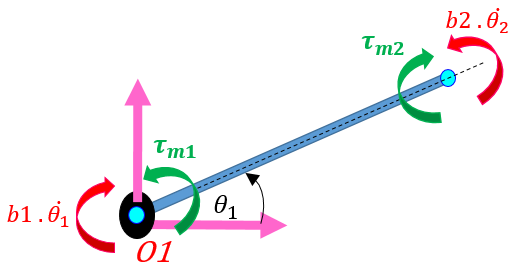

the_tau_mat_LINK_1 = [ ...
       (taum1_s),   (-b1_s*th1dot),   (-taum2_s),      (b2_s*th2dot); 
               0,                0,            0,                  0;          
               0,                0,            0,                  0;    ]; 
       
the_w_mat_LINK_1 = [ ...
    BF_rot_vel_B1,    BF_rot_vel_B1,   BF_rot_vel_B1,    BF_rot_vel_B1 ];

And similarly for **LINK #2**:

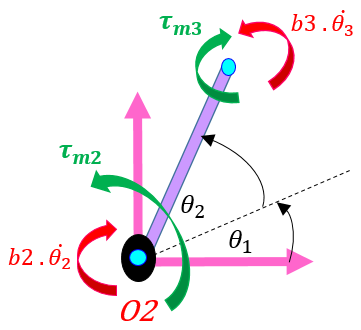

the_tau_mat_LINK_2 = [ ...
       (taum2_s),   (-b2_s*th2dot),   (-taum3_s),     (b3_s*th3dot);    
               0,                0,            0,                  0;          
               0,                0,            0,                  0;  ];        
   
the_w_mat_LINK_2 = [ ...
    BF_rot_vel_B2,    BF_rot_vel_B2,   BF_rot_vel_B2,    BF_rot_vel_B2 ];

And similarly for **LINK #3**:

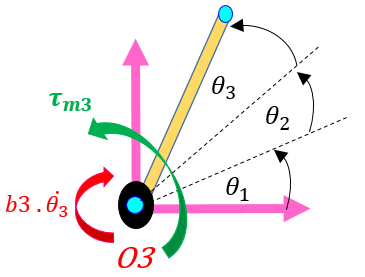

the_tau_mat_LINK_3 = [ ...
     (taum3_s),     (-b3_s*th3dot);            
             0,                  0;          
             0,                  0;  ];

the_w_mat_LINK_3 = [ ...
     BF_rot_vel_B3,         BF_rot_vel_B3 ];

And similarly for the turntable (ie: **LINK #4**):  $^{B4}\omega_4 \rightarrow$ `BF_rot_vel_B4`

   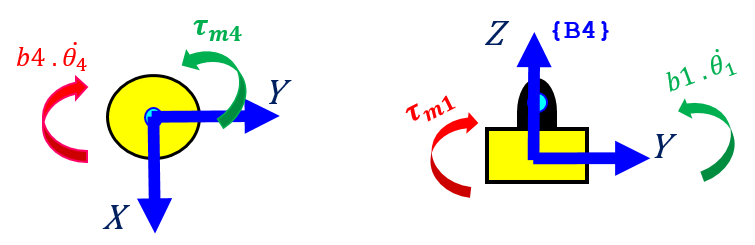

the_tau_mat_LINK_4 = ...
   [            0,                  0,      (b1_s*th1dot - taum1_s);          
                0,                  0,                            0;          
        (taum4_s),     (-b4_s*th4dot),                            0;   ];

the_w_mat_LINK_4 = [ ...
    BF_rot_vel_B4,      BF_rot_vel_B4,               BF_rot_vel_B4   ];     

Next, let's concatenate these into single matrices:

the_tau_mat_actual = [the_tau_mat_LINK_1, the_tau_mat_LINK_2, the_tau_mat_LINK_3,  the_tau_mat_LINK_4];
the_w_mat_actual   = [  the_w_mat_LINK_1,   the_w_mat_LINK_2,   the_w_mat_LINK_3,    the_w_mat_LINK_4];

Now let's compute $Q_k$:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


To do this we'll create a generalised force object using the class <`bh_genF4manips_CLS`>

genF_OBJ = bh_genF4manips_CLS( the_tau_mat_actual, ...
                               the_w_mat_actual, ...
                               actual_list_SYM_pos, ...
                               holder_list_SYM_pos);

And now calculate our system's generalised forces:                          

genF_OBJ = genF_OBJ.calc_genF();

What do the $Q_k's$ look like?

genF_OBJ.show_genF_holder()

Or we can retrieve all of the $Q_k's$ as a vector:

the_Qk_vec = genF_OBJ.get_Qk('all', 'holder')

## Absorb the Generalised Forces:

We can now insert these Generalised forces into the "Lagrangian" object that we created earlier, and then recalculate the equations of motion:

lag_OBJ = lag_OBJ.calc_eom(genF_OBJ);

 Now echo our equations:

lag_OBJ.get_eom( 1:4, 'holder', 'RHS')

## Now let's get the M,C,K,G,Q matrices:

We can express our system equations of motion in the following form:


$$M(q).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q$$


 lag_OBJ = lag_OBJ.create_MCKGQ();

Retrieve the MCKGQ struct:

res_T = lag_OBJ.get_MCKGQ()

And let's have a look at each of these terms:

Here's **M**:

res_T.M

Here's **C**:

res_T.C

Here's **K**:

res_T.K

Here's **G**:

res_T.G

Here's **Q**:

res_T.Q

## Now create the MATLAB function blocks for Simulink:

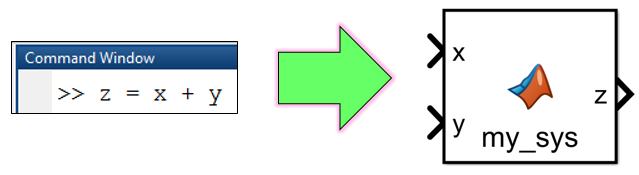

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

lag_OBJ.create_MLF_blocks()

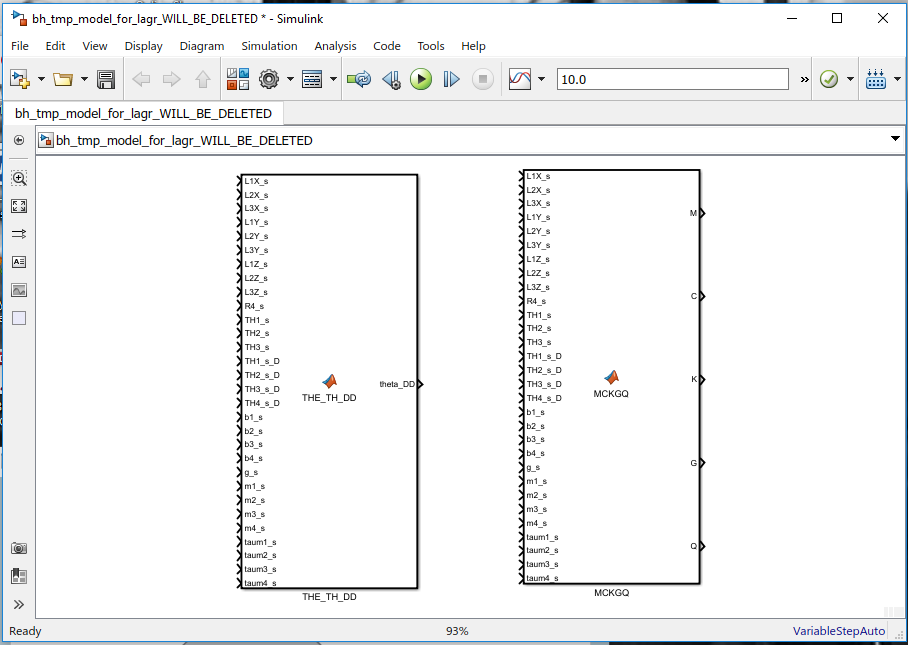

The "MCKGQ" block can then be pasted into a Simulink model for you to use in a simulation of the robot.  Why not use the DEMO_SELECTOR app to look at 2 such examples:

- In Example 1 we validate the derived model against a Simscape Multibody model

- In Example 2 we have a "complete" control system that makes our model write *"Hello"*